# Applying correction schemes for border effects and tangential motion

Here we show the functionality of the different approaches contained in this tool box by applying them to a paradigmic model system, similar to the procedure in the paper. 

We will generate synthetic data derived from the well known  [Roessler system](https://en.wikipedia.org/wiki/Rössler_attractor)

                                                    
$$\dot{x} = -y -z \\
\dot{y} = x + ay \\
\dot{z} = b + (x-c)z$$


For this system we consider two choices of the control parameters *a,b,c*, in order to obtain regular limit cycle behavior as well as chaotic motion. 

clear, clc

## 0) Parameter setting and preallocation

Set length of the time series output and the number of data points, which will be removed due to transient behavior.

N = 1000; 
transients = 2500;

Select the threshold selection method and the recurrence threshold $\epsilon$:

For the flow data we apply a fixed recurrence threshold corresponding to a global recurrence rate of 15% (we take the 15th percentile of all pairwise distances, cf. [Kraemer et al., Chaos 28, 085720 (2018)](https://aip.scitation.org/doi/abs/10.1063/1.5024914))

thres_sel_1 = 'var';
e1 = 0.15;

To mimic a more realistic case, we can also add white noise to the data. Select the noise level (times the mean standard deviation of the multivariate signal)

% sigma = 0; % 0% of the mean std of the signal, i.e. no noise contamination
sigma = 0.1; % 10% of the mean std of the signal
% sigma = 0.3; % 30% of the mean std of the signal

Select the metric for distance computations and choose from Euclidean or maximum norm.

norm = 'euc';
% norm = 'max';

The proposed correction schemes for border effects can correct for border diagonals (diagonal lines getting cut from both sides by the edges of the RP) or also take semi-border diagonals into account (diagonal lines getting cut from both OR just from one side by the edge of the RP).

% type = 'normal';
type = 'semi';

Preallocate storing vectors/matrices:

t = zeros(2,N); % time vectors for for regular and chaotic flow data

Y1 = cell(1,2); % phase space vectors for regular and chaotic flow data

RP1 = cell(6,2); % recurrence plots for regular and chaotic flow data

hl1 = cell(5,2); % all diagonal lines for regular and chaotic flow data

pl1 = cell(5,2); % histogram of diagonal lines for regular and chaotic flow data

ent_Sum1 = cell(2,6); % entropies for regular and chaotic flow data

## 1) Generate synthetic data

Set random number generator (for reproducibility)

rng(1)

## 1.1) Flow data

Roessler system in two parameter settings, leading to regular and chaotic motion (we choose a sampling time of $\Delta t = 0.2$, but you can vary this)

% initial condition
x0 = [2*rand();2*rand();2*rand()];

% parameters
a = 0.15;
b(1) = 10; % parameter leading to regular motion
b(2) = 0.2; % parameter leading to chaotic motion
c = 10;

% select the sampling time
delta_t = 0.2;

% integrate Roessler system with given parameters
[t(1,:),Y1{1}] = Rossler(a,b(1),c,x0,N,transients,delta_t);
[t(2,:),Y1{2}] = Rossler(a,b(2),c,x0,N,transients,delta_t);

Y1{1} = Y1{1}';
Y1{2} = Y1{2}';

Y1{1} = Y1{1} + sigma*mean(std(Y1{1}))*randn(size(Y1{1}));
Y1{2} = Y1{2} + sigma*mean(std(Y1{2}))*randn(size(Y1{2}));
    

Plot Phase Space for the Roessler system examples

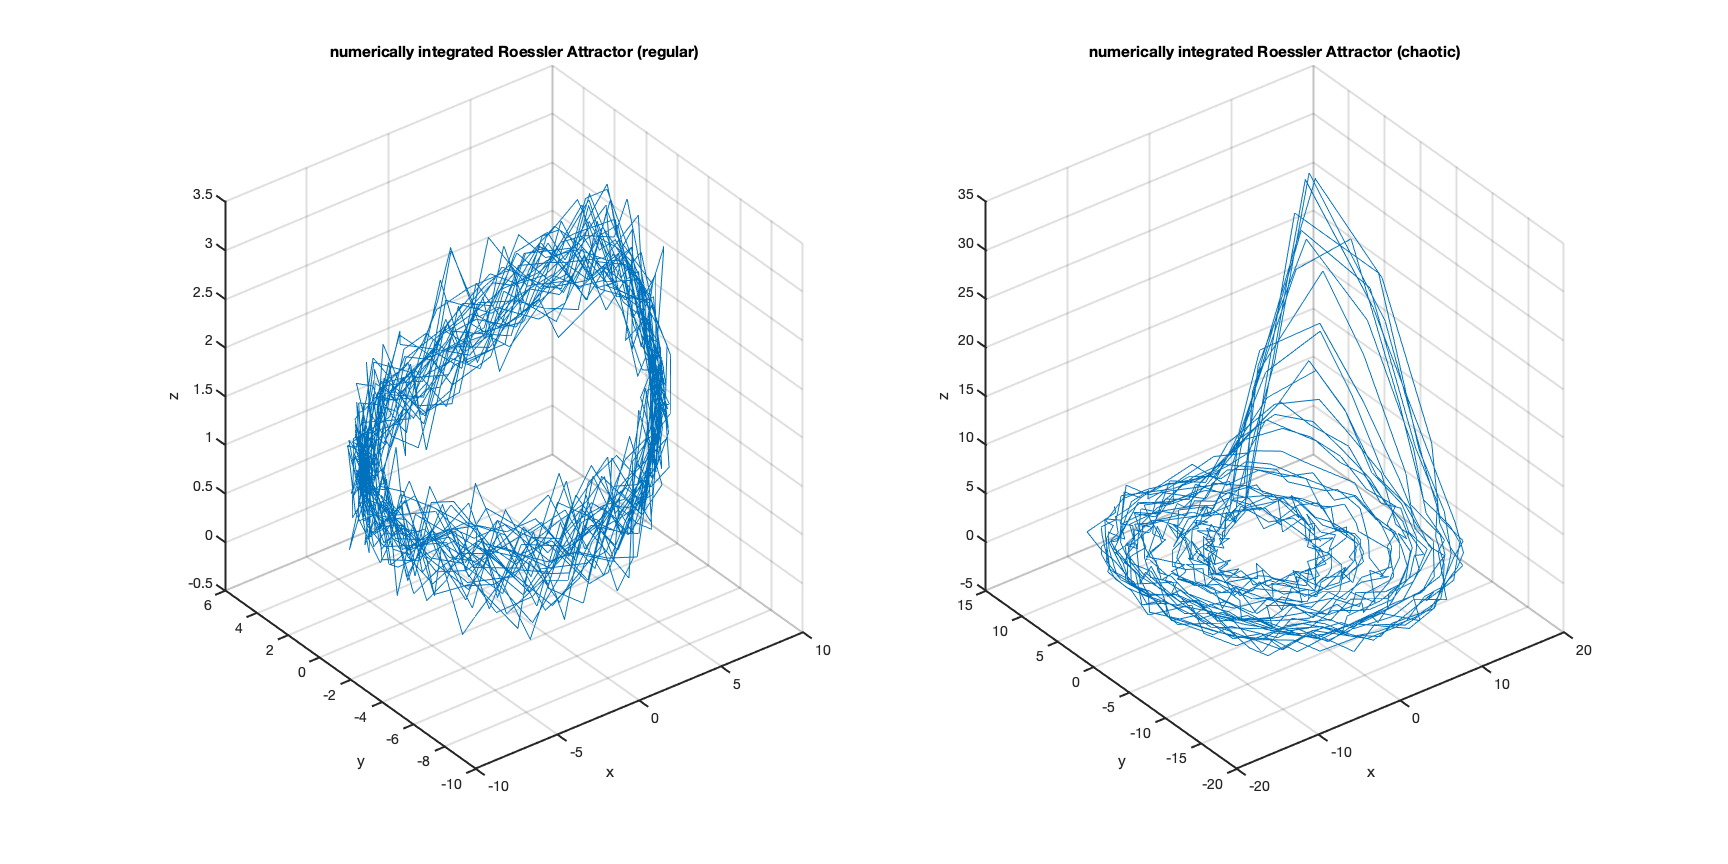

% Plot sampled Phase Space
figure('Units','normalized',...
    'Position',[.2 .2 .9 .8])

subplot(1,2,1)
plot3(Y1{1}(:,1),Y1{1}(:,2),Y1{1}(:,3))
xlabel('x')
ylabel('y')
zlabel('z')
title('numerically integrated Roessler Attractor (regular)')
set(gca,'Linewidth',2)
set(gca,'Fontsize',14)
grid on

subplot(1,2,2)
plot3(Y1{2}(:,1),Y1{2}(:,2),Y1{2}(:,3))
xlabel('x')
ylabel('y')
zlabel('z')
title('numerically integrated Roessler Attractor (chaotic)')
set(gca,'Linewidth',2)
set(gca,'Fontsize',14)
grid on

## 2) Compute RPs and diagonal line length histograms of border correction schemes

Now we compute conventional RPs of the data generated in the preceding section. On these RPs we apply the discussed border correction schemes and eventually display the corresponding histograms of diagonal line lengths.

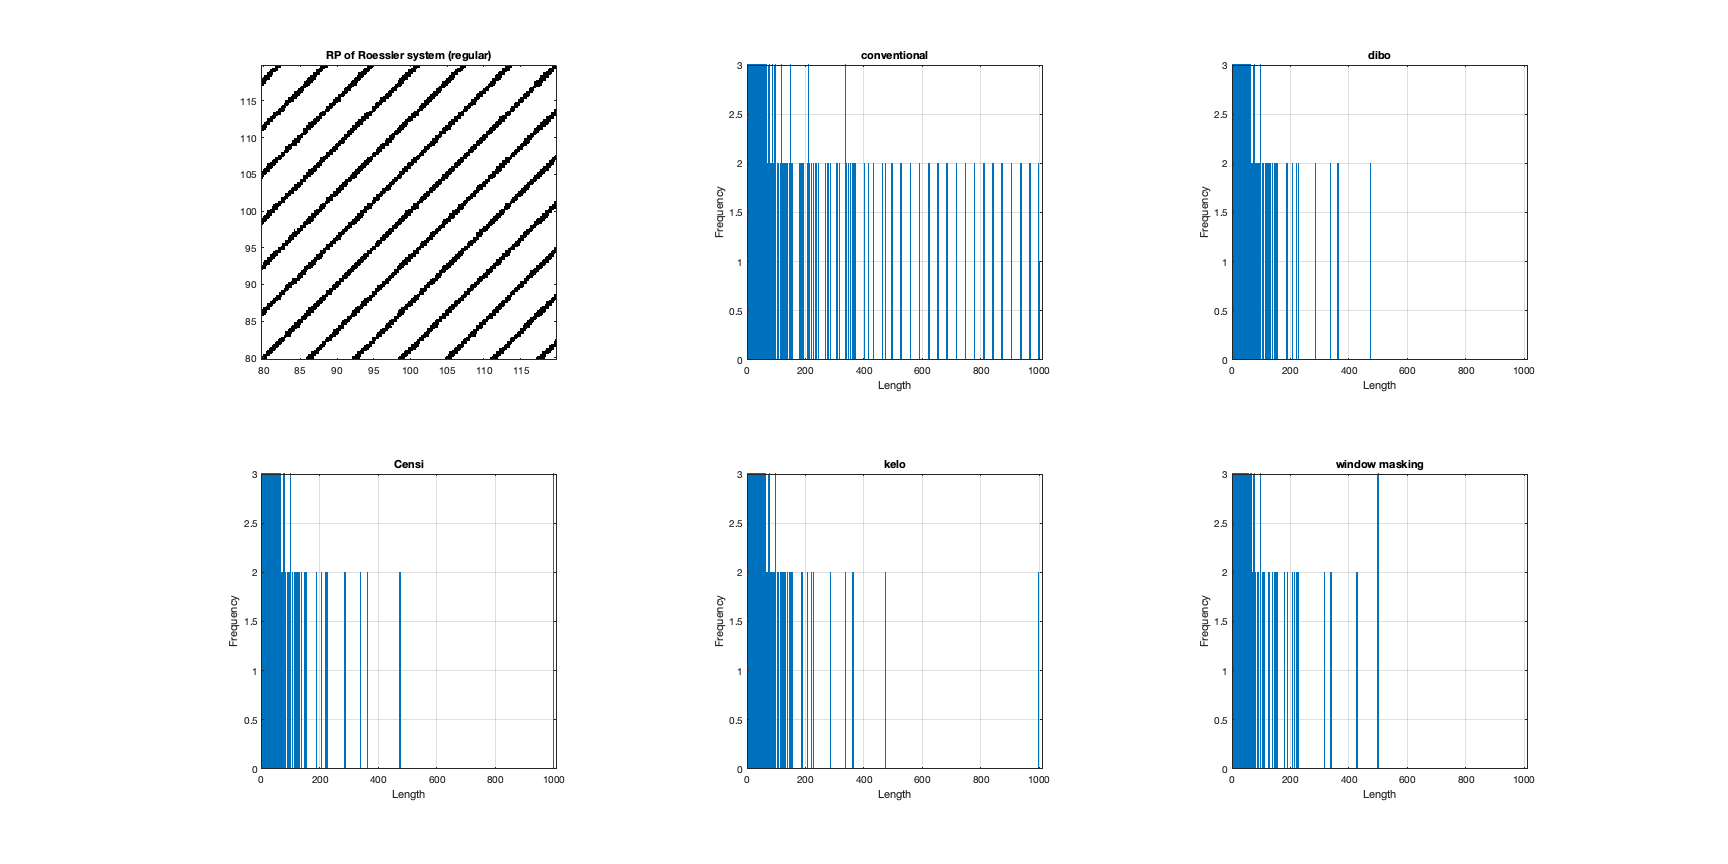

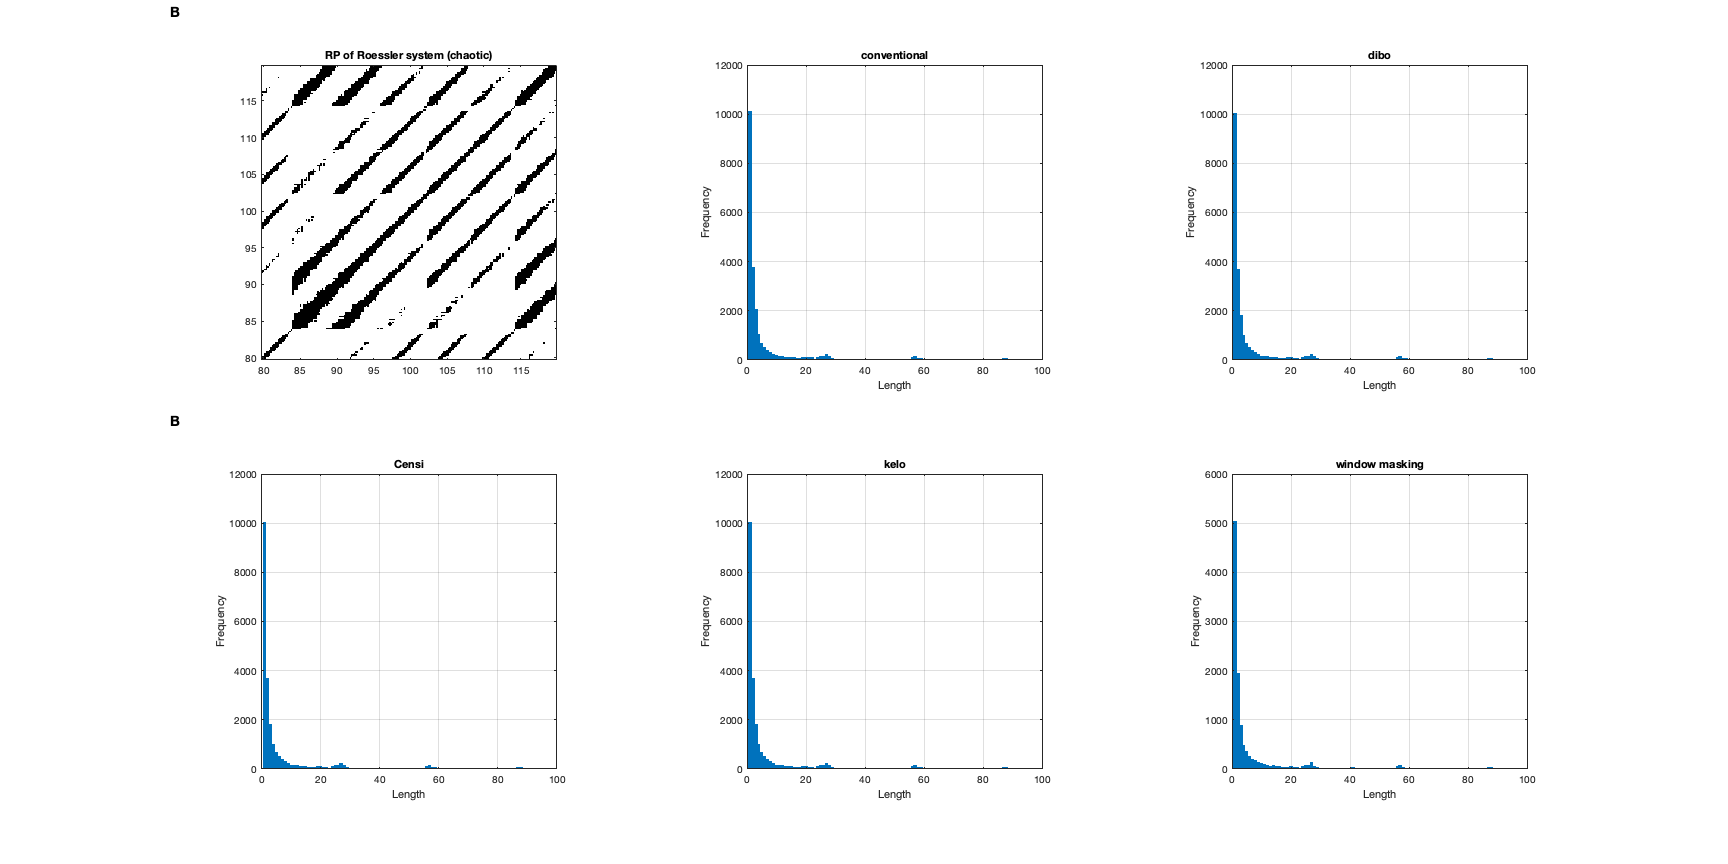

% loop over the two different regimes (regular and chaotic)
for i = 1:2  
    
    % compute normal RPs for the Roessler system
    [RP1{1,i},~,epsilon] = rp(Y1{i},e1,thres_sel_1,norm);     
    
    X1=RP1{1,i};
    
    % get line distributions    
    [~, hl1{1,i}] = dl_conventional(X1); % black diagonal lines conventional
    
    [~, hl1{2,i}] = dl_dibo(X1,type); % dibo correction
    
    [~, hl1{3,i}] = dl_censi(X1,type); % Censi correction 
    
    [~, hl1{4,i}] = dl_kelo(X1,type); % kelo correction
        
    [~, hll] = dl_windowmasking(X1); % window masking
    hl1{5,i} = hll(1,:)';
       
    % loop over the different border effect correction approaches and make
    % a proper histogram
    for l = 1:5       
        % make proper histogram
        pl1{l,i} = hist(hl1{l,i},1:size(RP1{1,i},1)); 
    end
        
    % create string array for storing title names of the subplot, which we
    % will plot for all the correction schemes
    titlestr = {'conventional','dibo','Censi','kelo','window masking'};
    
    % Plot results for the Roessler system
    figure('Units','normalized',...
        'Position',[.1 .1 .9 .8])

    subplot(2,3,1)
    imagesc(t(i,400:600),t(i,400:600),RP1{1,i}(400:600,400:600)), colormap([1 1 1; 0 0 0]), axis xy square
    if i == 1
        title('RP of Roessler system (regular)')
    else
        title('RP of Roessler system (chaotic)')
    end
    
    for l = 1:5
        subplot(2,3,l+1)
        h = bar(1:size(RP1{1,i},1),pl1{l,i});
        col = get(h,'facecolor'); % color of the bar plot
        set(h,'edgecolor',col,'linewidth',1) % use the color also for surrounding line
        axis square
        xlabel('Length'),ylabel('Frequency')
        title(titlestr{l})
        set(gca,'LineWidth',1)
        set(gca,'FontSize',10) 
        yl = ylim; xl = xlim;
        text(xl(1) - .3*range(xl),yl(2) + .18*range(yl),char(64+i),'FontWeight','bold','FontSize',14)      
        
        % set x- and y- limits in the plots
        if i == 1
            ylim([0 3])
            xlim([0 N+10])
        else
            xlim([0 N/10])            
        end
        grid on
    
    end
    
    
end

## 3) Tangential motion correction schemes

For all tangential motion corrections schemes, but our proposed diagonal RP skeletonization method, we have to set the according parameters:

% perpendicular RP: angle threshold
w = 0.258; % this is in rad units and corresponds to roughly 15°

% isodirectional RP: translation parameter T
% (corresponds roughly to the first minimum of the auto mutual information
% for the chaotic and regular Roessler setup )
T = 7;

% isodirectional RP: choice of second recurrence threshold. Give this as a
% percentage of the first recurrence threshold, i.e. if set to 0.8, the
% second threshold will be e2 = 0.8 * e1
iso_threshold_factor = 0.8;

% TRP threshold
% (corresponds roughly to the first minimum of the auto mutual information
% for the chaotic and regular Roessler setup)
TRP_threshold = 7;

% LM2P RP threshold
% (corresponds roughly to the first minimum of the auto mutual information
% for the chaotic and regular Roessler setup)
LM2P_threshold = 7;

## 3.1) Compute and display RPs from the tangential motion correction schemes

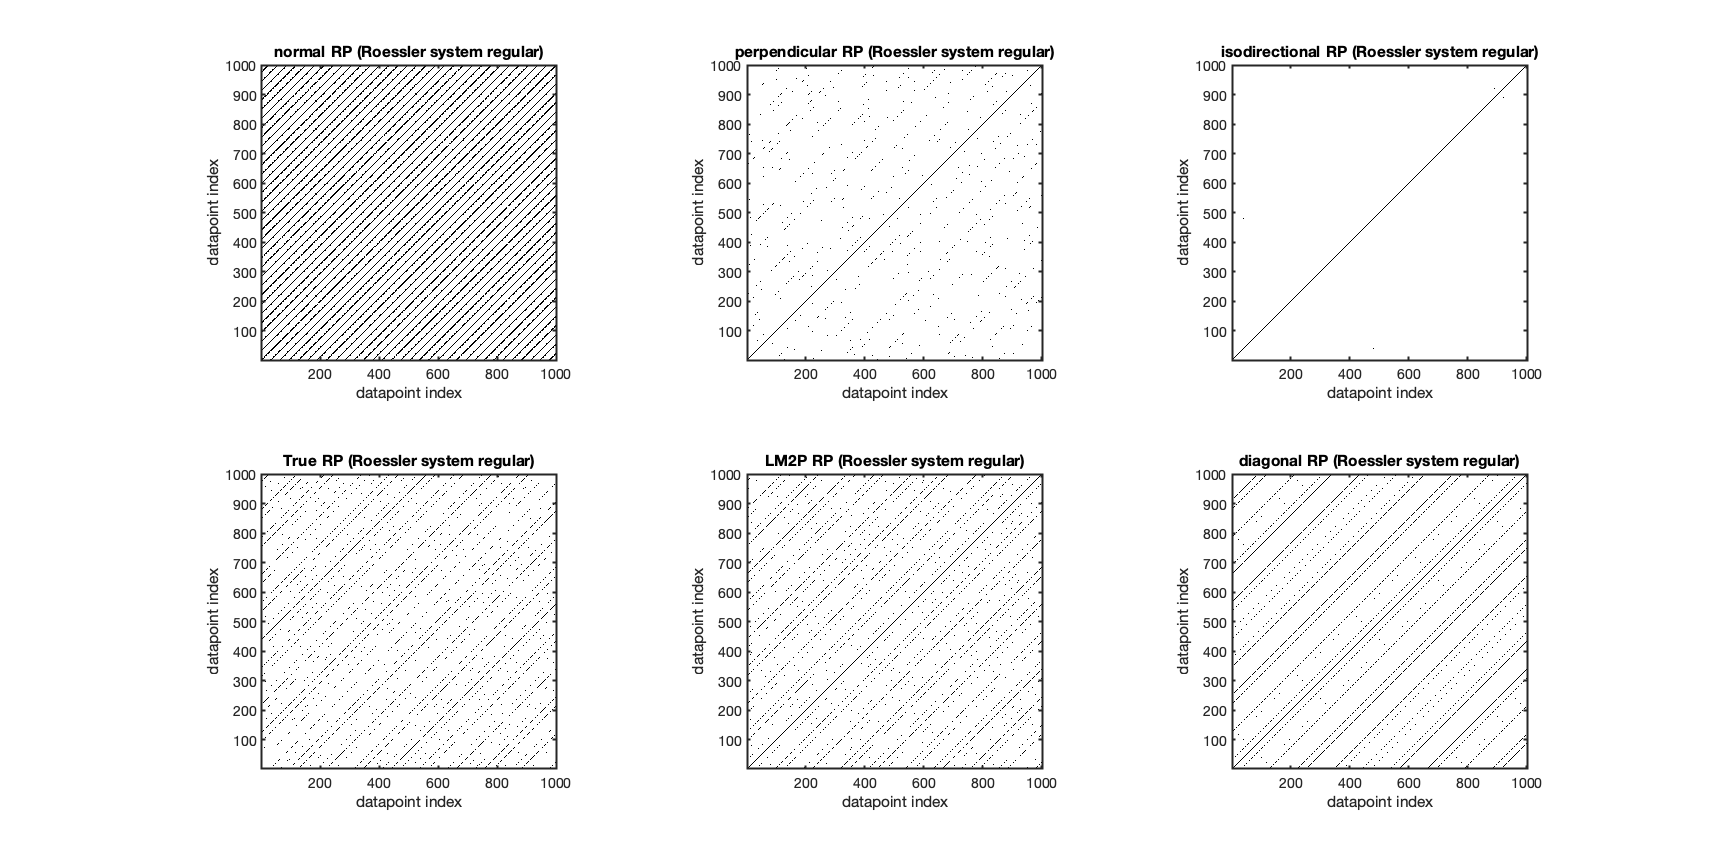

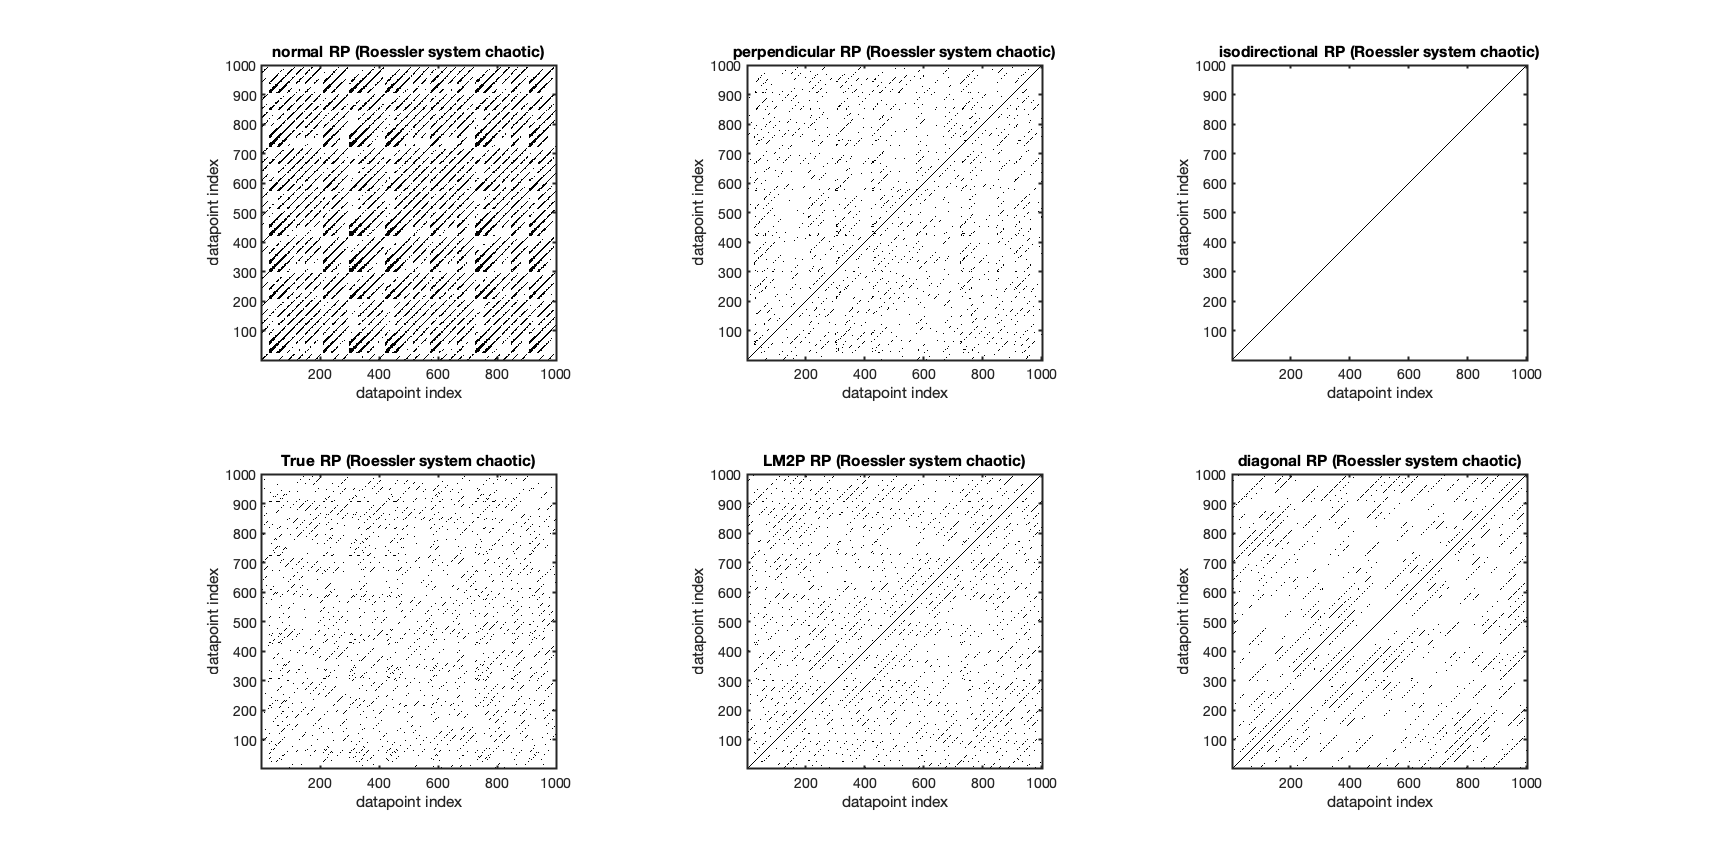

% loop over the two different regimes
for i = 1:2    
    % apply correction schemes for tangential motion
   
    % Roessler system data
    RP1{2,i} = rp_perp(Y1{i},e1,thres_sel_1,w,2,norm);
    RP1{3,i} = rp_iso(Y1{i},e1,(e1*iso_threshold_factor),thres_sel_1,T,norm);
    RP1{4,i} = rp_TRP(Y1{i},e1,thres_sel_1,TRP_threshold,norm); 
    RP1{5,i} = rp_LM2P(Y1{i},e1,thres_sel_1,LM2P_threshold,norm);
    RP1{6,i} = rp_diagonal(RP1{1,i});
      
    % plot results 
    
    methods = {'normal','perpendicular','isodirectional','True','LM2P',...
        'diagonal'};
    
    
    % Roessler system
    
    figure('Units','normalized',...
         'Position',[.1 .1 .9 .8])
    % loop over the correction schemes
    for j = 1:6
        
        subplot(2,3,j)
        imagesc(RP1{j,i}), colormap([1 1 1; 0 0 0]), axis xy square
        if i == 1
            titlestring = strcat(methods{j},'{ }','RP (Roessler system regular)');
            title(titlestring)
        else
            titlestring = strcat(methods{j},'{ }','RP (Roessler system chaotic)');
            title(titlestring)
        end
        xlabel('datapoint index')
        ylabel('datapoint index')
        set(gca,'LineWidth',2)
        set(gca,'FontSize',14)     
    end
      
end

## 3.2) Compute and display entropy from the tangential motion correction schemes

Choose the minimal line length (i.e. the number of diagonally adjacent recurrence points in the recurrence plot (RP), which are considered as a diagonal line). This parameter is crucial for obtaining meaningful results for the diagonal line length entropy in the presence of noise, i.e. if you have chosen $\sigma \neq 0$ in lines 6-8

l_min = 2;

Start computation and plotting:

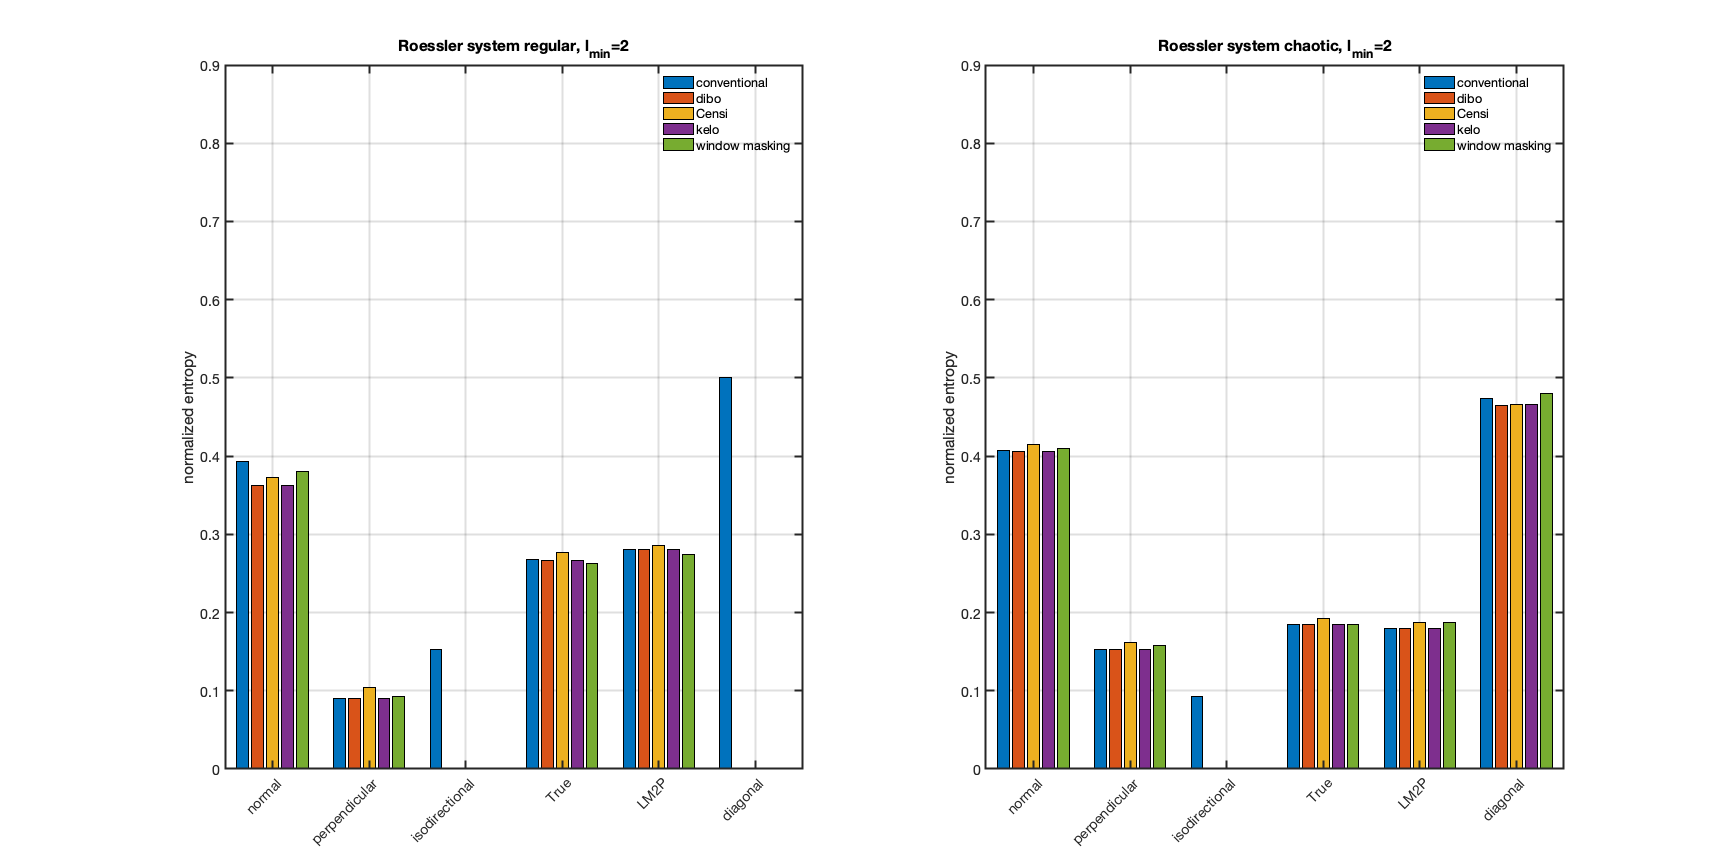

% loop over the two different regimes
for i = 1:2
    
    % loop over the different tangential motion correction schemes
    
    for j = 1:6
        
        X1 = RP1{j,i};
        
        % get line distributions    
        [~, hl1{1,i}] = dl_conventional(X1); % black diagonal lines conventional

        [~, hl1{2,i}] = dl_dibo(X1,type); % dibo correction

        [~, hl1{3,i}] = dl_censi(X1,type); % Censi correction 

        [~, hl1{4,i}] = dl_kelo(X1,type); % kelo correction

        [~, hll] = dl_windowmasking(X1); % window masking
        hl1{5,i} = hll(1,:)';
        
        % loop over the different border effect correction approaches and make
        % a proper histogram
        for l = 1:5       
            % make proper histogram
            pl1{l,i} = hist(hl1{l,i},1:size(RP1{j,i},1)); 
            
            % adjust histograms to chosen minimal line length
            pl1{l,i} = pl1{l,i}(l_min:end);
            
            % compute diagonal line length entropy

            % get probability distribution from histogram
            l_prob1 = pl1{l,i}/sum(pl1{l,i});

            ent_Sum1{i,j}(l) = nansum(-l_prob1 .* log(l_prob1))/log(length(pl1{l,i}));
        end
        
    end  
    
    % for bar plot visualization, create grouped-vector-values
    yy1 = [ent_Sum1{i,1}(1),ent_Sum1{i,1}(2),ent_Sum1{i,1}(3),ent_Sum1{i,1}(4),ent_Sum1{i,1}(5);...
    ent_Sum1{i,2}(1),ent_Sum1{i,2}(2),ent_Sum1{i,2}(3),ent_Sum1{i,2}(4),ent_Sum1{i,2}(5);...
    ent_Sum1{i,3}(1),ent_Sum1{i,3}(2),ent_Sum1{i,3}(3),ent_Sum1{i,3}(4),ent_Sum1{i,3}(5);...
    ent_Sum1{i,4}(1),ent_Sum1{i,4}(2),ent_Sum1{i,4}(3),ent_Sum1{i,4}(4),ent_Sum1{i,4}(5);...
    ent_Sum1{i,5}(1),ent_Sum1{i,5}(2),ent_Sum1{i,5}(3),ent_Sum1{i,5}(4),ent_Sum1{i,5}(5);...
    ent_Sum1{i,6}(1),ent_Sum1{i,6}(2),ent_Sum1{i,6}(3),ent_Sum1{i,6}(4),ent_Sum1{i,6}(5)];
    
    
    % Plot entropies
      
    % Roessler system
    if i == 1
        f2 = figure('Units','normalized',...
             'Position',[.1 .1 .9 .8]);
    else
        set(0, 'currentfigure', f2);
    end
        
    subplot(1,2,i)       
    c = bar(1:6,yy1);
    set(gca,'xticklabel',{methods{1},methods{2},methods{3},...
        methods{4},methods{5},methods{6}})
    xtickangle(45)
    set(gca,'LineWidth',2)
    set(gca,'FontSize',14) 
    legend(c,titlestr{1},titlestr{2},titlestr{3},...
            titlestr{4},titlestr{5})
    legend boxoff
    ylabel('normalized entropy')
    ylim([0 .9])
    grid on
    
    if i == 1
        titlestringX = strcat('Roessler system regular, l_{min}=',num2str(l_min));
        title(titlestringX)
    else
        titlestringX = strcat('Roessler system chaotic, l_{min}=',num2str(l_min));
        title(titlestringX)
    end
    
    
end

## Helper functions

function [t2,x2] = Rossler(varargin)
% This function numerically integrates the Roessler-System with input
% paramters 'a', 'b' and 'c' starting with input inital condition 
% x0 = [x(t0); y(t0); z(t0)]. 
%
% [t,x] = Rossler(a,b,c,x0,N,transients,delta_t)
%
% t is the time vector containing just the times, where the samping took
% place (sampling time input 'delta_t'). The corresponding values to these 
% times are stored in x.
%
% The output is a vector-series of length 'N' (input parameter) with 'transients'
% removed samples.


% bind input
a = varargin{1};
b = varargin{2};
c = varargin{3};
x0= varargin{4};
N = varargin{5};
transients = varargin{6};
time_sample = varargin{7};

time_interval = (N+transients)* time_sample;     % k+1 is the number of columns in the solution matrix M

% This results in a corresponding time vector
t2 = 0:time_sample:time_interval;

 
f = @(t,x) [-x(2)-x(3); x(1)+a*x(2); b+x(3)*(x(1)-c)];  % Rossler system
SOL = ode45(f,[t2(1) t2(end)],x0);
    
x2 = deval(SOL,t2);

% Store sampled time series    
x2 = x2(:,transients+1:end-1);
t2 = t2(1:end-transients-1);

end